clear all; clc;

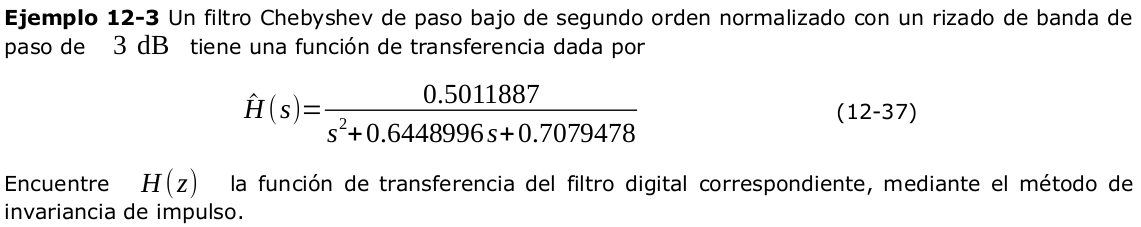

**función de transferencia**

syms s;
H(s)=0.5011887/(s^2+0.6448996*s+0.7079478);

**respuesta en frecuencia s**

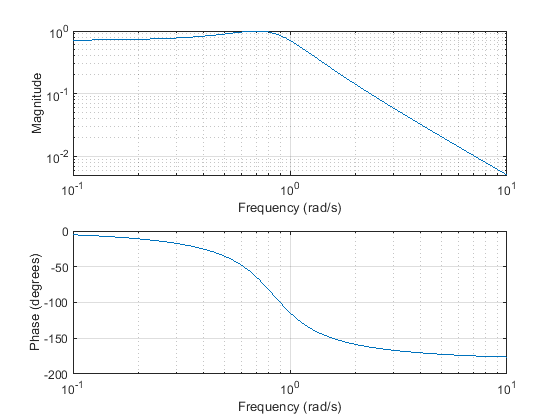

[B,A]=numden(H(s));
b= sym2poly(collect(B));
a= sym2poly(collect(A));
w=logspace(-1,1);
clf, freqs(b,a,w);

**Integración numérica - método de euler**

syms z, syms T 'real';
HzT(z)=subs( H(s), s=(1-z^-1)/T );
HzT(z)=collect(HzT(z),z^-1 )

$$HzT(z) = \frac{4.5143e+15\,T^{2}\,z^{2}}{\left(6.3766e+15\,T^{2}+5.8087e+15\,T+9.0072e+15\right)\,z^{2}+\left(-5.8087e+15\,T-1.8014e+16\right)\,z+9.0072e+15}$$

**Evaluando para un periodo de muestreo igual a 1**

Hz(z)=subs(HzT(z),T=sym(100000))

$$Hz(z) = \frac{4.5143e+25\,z^{2}}{6.3767e+25\,z^{2}-5.8089e+20\,z+9.0072e+15}$$

**Respuesta en frecuencia**

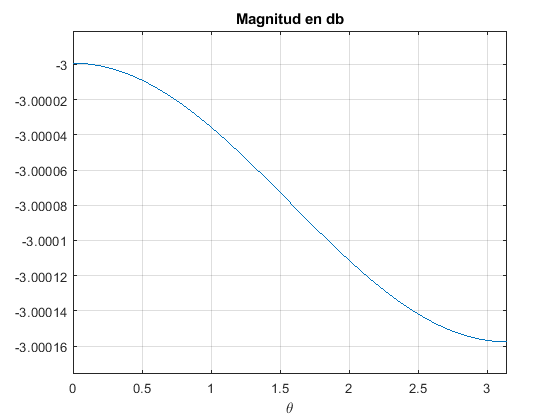

syms theta 'real';
clf; ezplot(20*log10(abs(Hz(exp(j*theta)))),[0,pi]),
title('Magnitud en db'); grid on;

**respuesta en frecuencia**

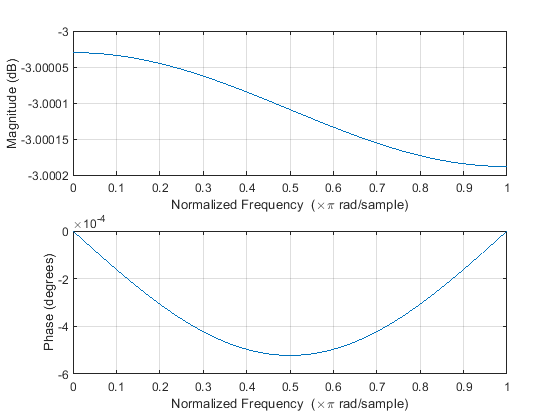

[Bz,Az]=numden(collect(Hz(z)));
bz=sym2poly(Bz); az=sym2poly(Az);
clf; freqz(bz, az, 100000)